% This is the testing file for scan conversion

fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Single checkerboard
% B = zeros(h,w);
% B(1:2:h,1:2:w) = ones(ceil(h/2),ceil(w/2));
% B(2:2:h,2:2:w) = ones(floor(h/2),floor(w/2))

% Double checkerboard
% B = zeros(h,w);
% B(1:4:h,1:4:w) = ones(ceil(h/4),ceil(w/4));
% B(1:4:h,2:4:w) = ones(ceil(h/4),floor(w/4));
% B(2:4:h,1:4:w) = ones(floor(h/4),ceil(w/4));
% B(2:4:h,2:4:w) = ones(floor(h/4),floor(w/4));
% 
% B(3:4:h,3:4:w) = ones(ceil(h/4),ceil(w/4)-1);
% B(3:4:h,4:4:w) = ones(ceil(h/4),floor(w/4));
% B(4:4:h,3:4:w) = ones(floor(h/4),ceil(w/4)-1);
% B(4:4:h,4:4:w) = ones(floor(h/4),floor(w/4))


% Make block
a = 1000

a = 1000

b = 2000

b = 2000

c = 6

c = 6

d = 12

d = 12


B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

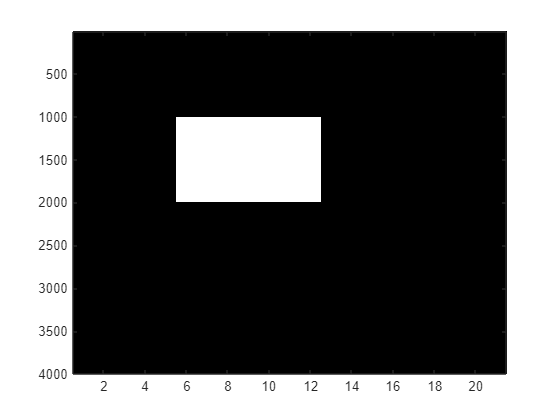


figure
colormap(gray)
imagesc(B)


% All ones to view beams
% B = ones(h,w);

imager = 101;
imagec = 201;
ishiftr = floor(imager/2);
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

% Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas; % have spearate lookups for image and for beams??



%precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;


%precompute image rvals
rvals = zeros(imager,imagec);
for rr=1:imager
    for cc=1:imagec
        r = rr-1;
        c = cc - ishiftc - 1;
        rvals(rr,cc) = sqrt(r^2+c^2)/100;
    end
end
rvals;


% for px = 1:imagec
%     for py = 1:imager
%         r = rvals(py,px);
%         n = floor(r*Fs/c);
% 
%         theta = thetas(py,px);
%         k = floor(sin(theta)/2*Fs/fc);
%         kk = k + shift;
%         if (n < h) && (kk < w)
%             blah = B(n,kk);
%         end
%     end
% end
% n
% k
% blah

image = zeros(imager,imagec);


rfpp = (imager-1)/rs(end,1)

rfpp = 4.4025

cfpp = (imagec/2-1)/rs(end,1)

cfpp = 4.3805


aspectRatio = cfpp/rfpp

aspectRatio = 0.9950

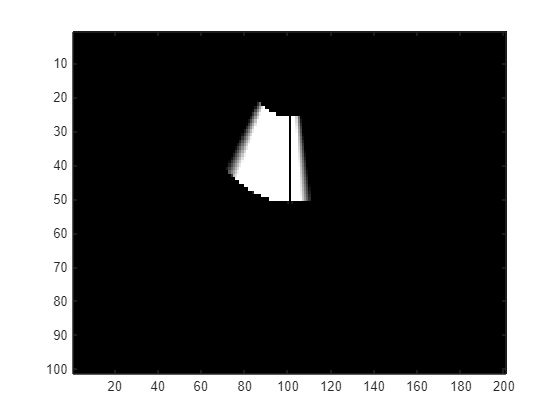



% Put things in beams onto image
% tic
% for kk = 1:w
%     k = kk-shift;
%     for n = 1:h
%         r = rs(n,kk);
%         theta = thetas(n,kk);
% 
%         y = floor(r*cos(theta)*rfpp);
%         x = round(r*sin(theta)*cfpp);
% 
%         image(y+1,x+1+ishiftc) = B(n,kk);
%     end
% end
% time = toc
% his time is 0.0466669 but also interpolates



%image = ones(imager,imagec)-image;

% figure
% colormap(gray)
% imagesc(image)

% Now, need to interpolate
image_interp = image;
max_distance = rs(end,1);

for pc = 1:imagec
    for pr = 1:imager
        
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;

        rp = sqrt(px^2+py^2);

        if (rp <= .99*max_distance)
            thetap_test = atan(pc/pr);
            thetap = atan(px/py);

            if (px ~= 0)
                kp = sin(thetap)/2*Fs/fc;
            else
                kp =  0;
            end

            k = floor(kp);
            if (kp ~= k)
                k1 = k+1;
                kk = k+11;
                kk1 = k1+11;
        
                np = rp/C*Fs;
                n = floor(np)+1;
                n1 = n+1;
        
                r = rs(n,1);
                r1 = rs(n1,1);
                dr = r1-r;
        
                theta = thetas(1,kk);
                theta1 = thetas(1,kk1);
                dtheta = theta1-theta;
        
                beta = (rp - r)/dr;
                alpha = (thetap - theta)/dtheta;
        
                image_interp(pr,pc) = (1-beta)*((1-alpha)*B(n,kk)+alpha*B(n,kk1)) + beta*((1-alpha)*B(n1,kk) + alpha*B(n1,kk1));
            else
                image_interp(pr,pc) = image(pr,pc);
            end
        else
            image_interp(pr,pc) = 0;
        end

    end
end

figure
colormap(gray)
imagesc(image_interp)


image_interp;

% compare
test_image = scan_conversion(B, 19, 2000, 10, 100)

figure
colormap(gray)
imagesc(test_image)

% Figuring out data thing

load sc_image.mat -mat

sc_image

figure
imagesc(sc_image)

% Turning it into a function